# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

Check that MATLAB can recognize the Python installation. (Use `pyversion` if using a MATLAB release before R2019b)

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.6"
       Executable: "C:\Python36\WPy-3670\python-3.6.7.amd64\python.EXE"
          Library: "C:\Python36\WPy-3670\python-3.6.7.amd64\python36.dll"
             Home: "C:\Python36\WPy-3670\python-3.6.7.amd64"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "6936"
      ProcessName: "MATLABPyHost"

Test a simple function.

py.math.sqrt(42)

ans = 6.4807

## Read weather data using Python module 

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("Boston","US",apikey.Key(1))

currentData = 1×12 table
         DateLocal            city        StateName        T        P        DP       RH     WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    _____    _____    ______    ____    _______    _______    ____    __    __
    22-Apr-2020 18:37:04    "Boston"    Massachusetts    43.34    24.75    369.86    1007     23.04       28       2020    4     22

Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

## Preprocess data 

The Python dictionary can be represented as a MATLAB struct.

data = struct(weatherData)

airQual = categorical
     Good 

Convert data to the desired MATLAB data types using the function below. 

convertData(data)

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

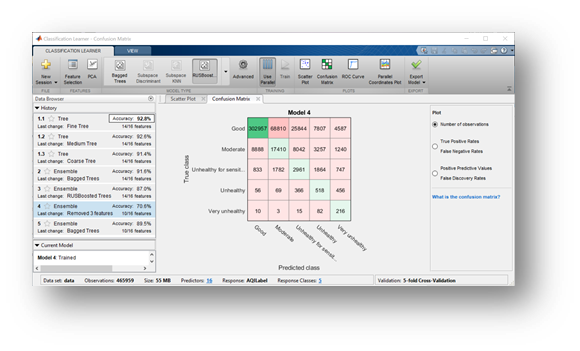

Use a function (`prepData.m`) to prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

Use the model to predict the air quality for the new weather data.

load airQualModel 

airQual = predict(model,currentData)

## Share prediction code

Create a function with these steps to be called in the Python environment.

edit predictAirQual.m

This function can now be tested in Python. See `CallMATLABfromPython.ipynb`

**Helper Function**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end